# BASELINE PERFORMANCE INF

Investigates performance of MPC-PD controller in infinite-horizon mode.

clear;

%params
tar = 3;

## cube0

%clean
if (exist('loop_real', 'var'))
    if ~(strcmp(loop_real, 'cube0_mpcpd'))
        set_param(loop_real, 'FastRestart', 'off');
        set_param(loop_model, 'FastRestart', 'off');
        close_system(loop_real);
        close_system(loop_model);
    end
end

%models
loop_real = 'cube0_mpcpd';
loop_model = 'cube0_mpcpd_model';
sc_real = 'cube0';
sc_model = 'cube0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on', 'SaveState', 'on', 'StateSaveName', 'states');

%params
t_tot = 200;

%mpcpd params
pred_horizon = 300;
cont_update = 300;
g = [1; 1; 1; 50; 50; 50];
iterations = 250;
learning_rate = 0.1;

### 1

1_cube0_baseline_1

%info
filename = '1_cube0_baseline_1';
info = 'inf1: 300 300 [1 1 1 50 50 50] 250 0.1 EG (e^2 + 0.01k^2)';

%params
costfunction = 1;

%sim and process
simmpcpd;

prepvisualise;

%clean
close all;
clearvars -except tar pred_horizon cont_update g iterations learning_rate sc_real sc_model loop_real loop_model aux t_tot;

### 2

1_cube0_baseline_2

%info
filename = '1_cube0_baseline_2';
info = 'inf2: 300 300 [1 1 1 50 50 50] 250 0.1 EG (e^2 + 1e-6w_rw^2 + 0.01k^2)';

%params
costfunction = 2;

%sim and process
simmpcpd;
prepvisualise;

%clean
close all;
clearvars -except tar pred_horizon cont_update g iterations learning_rate sc_real sc_model loop_real loop_model aux t_tot;

## cubewithpanels0

%clean
if (exist('loop_real', 'var'))
    if ~(strcmp(loop_real, 'cubewithpanels0_mpcpd'))
        set_param(loop_real, 'FastRestart', 'off');
        set_param(loop_model, 'FastRestart', 'off');
        close_system(loop_real);
        close_system(loop_model);
    end
end
clearvars -except tar;

%models
loop_real = 'cubewithpanels0_mpcpd';
loop_model = 'cubewithpanels0_mpcpd_model';
sc_real = 'cubewithpanels0';
sc_model = 'cubewithpanels0_model';

open(loop_real);
set_param(loop_real, 'FastRestart', 'on',  'SaveState', 'on', 'StateSaveName', 'states', 'MaxStep', '1');
open(loop_model);
set_param(loop_model, 'FastRestart', 'on', 'SaveState', 'on', 'StateSaveName', 'states');

%params
t_tot = 400;

%mpcpd params
pred_horizon = 500;
cont_update = 500;
g = [1; 1; 1; 50; 50; 50];
iterations = 250;
learning_rate = 0.1;

### 1

1_cubewithpanels0_baseline_1

%info
filename = '1_cubewithpanels0_baseline_1';
info = 'inf1: 500 500 [1 1 1 50 50 50] 250 0.1 EG (e^2 + 0.01k^2)';

%params
costfunction = 1;

%sim and process
simmpcpd;
prepvisualise;

%clean
close all;
clearvars -except tar pred_horizon cont_update g iterations learning_rate sc_real sc_model loop_real loop_model aux t_tot;

### 2

1_cubewithpanels0_baseline_2

%info
filename = '1_cubewithpanels0_baseline_2';
info = 'inf2: 500 500 [1 1 1 50 50 50] 250 0.1 EG (e^2 + 1e-6w_rw^2 + 0.01k^2)';

%params
costfunction = 2;

%sim and process
simmpcpd;
prepvisualise;

%clean
close all;
clearvars -except tar pred_horizon cont_update g iterations learning_rate sc_real sc_model loop_real loop_model aux t_tot;

### 3

1_cubewithpanels0_baseline_3

%info
filename = '1_cubewithpanels0_baseline_3';
info = 'inf3: 500 500 [1 1 1 50 50 50] 250 0.1 EG (e^2 + 2.5e4theta^2 + 0.01k^2)';

%params
costfunction = 3;

%sim and process
simmpcpd;

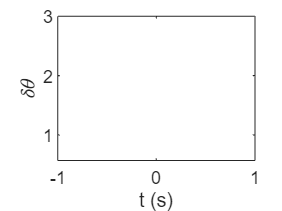

Error using matlab.internal.math.getdimarg
Dimension argument must be a positive integer scalar within
indexing range.

Error in cumtrapz>getDimArg (line 91)
    dim = matlab.internal.math.getdimarg(dim);

Error in cumtrapz (line 49)
    dim = min(ndims(y)+1, getDimArg(

prepvisualise;


%clean
close all;
clearvars -except tar pred_horizon cont_update g iterations learning_rate sc_real sc_model loop_real loop_model aux t_tot;